clear vars; close all; clc
format long
global A B C G P Z fre nn gamma x_eq tau 

nn = 3;           % number of ring cells
flag = 2;         % 0 - regular network, 1 - NONregular network, 2 - directed network
mp = 1.0;         % gain
ifi = 0;          % initial phase
tend = 1000;      % time 

### Individual Dynamics

A = [1 -1 1; 1 0 0; -4 2 -3];
B = [0;0;1];
C = [0 0 1];
P = lyap(A',eye(length(A)));
Z = B'*P;

### Network Structure

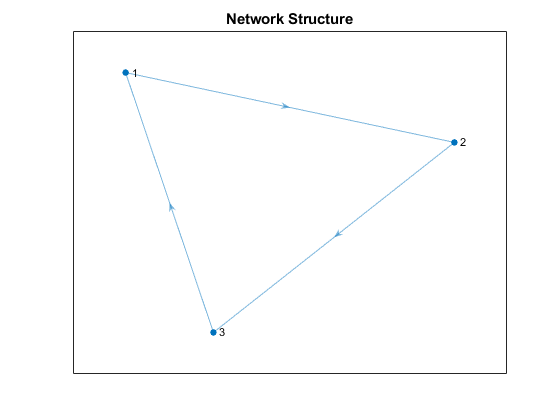

[G,n,offset] = NetworkStructure(nn,flag);

In=eye(n);

**Synchronized Equlibria analysis**

for i = 1:n

einval(i-1+1,:) = exp(-1i*(2*pi*(i-1))/3);
einvec(i-1+1,:) = [1; exp(-1i*(2*pi*(i-1))/3); exp(-1i*(2*pi*(n-1)*(i-1))/3)];

end

% eigenvalues_gamma = einval
% eigenvectors_gamma =einvec
% incon = eigenvectors_gamma(:,2);

### Equilibrium point(s) and Linearizaton

syms x1 x2 x3  s zu
assume (x1, 'real')
assume (x2, 'real')
assume (x3, 'real')

x = [x1;x2;x3];

J(x) = jacobian(A*x- B*Z*x.^3);
eqp = solve((A*x- B*Z*x.^3==0),x);
x_eq = [double(eqp.x1); double(eqp.x2); double(eqp.x3)];
J0 = double(J(eqp.x1, eqp.x2, eqp.x3));
huzwitzCrit(J0)

System is Stable



H(s) = C*((s*eye(length(J0)) - J0)^-1)*B;
H(s) = simplify(H(s));

w = 0:0.0001:1;

L = double(H(1i*w'));

[nu,i] = min(real(L));

om_star = w(i);
gamma_min = -1/(2*nu)

gamma_min =    0.648118932664360


gamma_min = 0.7110

gamma_min =    0.711000000000000



BC = B*C;

AA = kron(In,(J0-gamma_min*BC));
BB = kron(gamma_min*G,BC);

% eq1 = det(kronsum((AA + BB*zu),(AA'+ BB'*(1/zu))));
% crit1 = double(solve(eq1==0,zu));
% crit1m=[];
% f1=[];
% for i = 1:length(crit1)
%     ei = eig(AA + BB*crit1(i));
%     for ii = 1:length(ei)
%         if abs(real(ei(ii)))<10e-6 && imag(ei(ii))>0 
%             crit1m = [crit1m; crit1(i)];
%             f1 = [f1; imag(ei(ii))];
%         end
%     end   
% end
% 
% taus = sort((-1i*log(1./crit1m))./f1);
% taus = real(taus(taus>0))


### Most rigth eigenvalue of linearized network


addpath('files_roots')  


% gamma = 1.1*gamma_min
% tau = taus(1)

gamma = 0.7110

gamma =    0.711000000000000


tau = 6

tau =      6


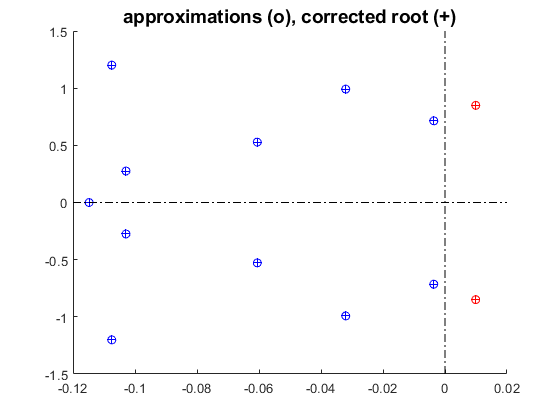


A0 = kron(In,(J0 - gamma*B*C));
A1 = kron(gamma*G,B*C);
hA = [0, tau];

tds = tds_create({A0, A1}, hA);
tds_check_valid(tds)
options=tdsrootsoptions;
options.minimal_real_part= -0.15;
[eigenvalues, N, size_eigenvalue_problem]=tds_charateristic_roots(tds, options);
figure(2)
eigenplot(eigenvalues)

eigenvalues.l1

ans =   0.009937358780635 + 0.849676598454039i
  0.009937358780635 - 0.849676598454039i
 -0.003609757908371 + 0.714437892122940i
 -0.003609757908371 - 0.714437892122940i
 -0.032065658766967 + 0.992064791608534i
 -0.032065658766967 - 0.992064791608534i
 -0.060551689899253 + 0.528335221858728i
 -0.060551689899253 - 0.528335221858728i
 -0.102903431641137 + 0.275420233723371i
 -0.102903431641137 - 0.275420233723371i


eigenvalues.l0

ans =   0.009919921958308 + 0.849653852387593i
  0.009919921958308 - 0.849653852387593i
 -0.003621855946200 + 0.714437384424212i
 -0.003621855946200 - 0.714437384424212i
 -0.032023051667106 + 0.992021193625670i
 -0.032023051667106 - 0.992021193625670i
 -0.060553522935019 + 0.528335192881265i
 -0.060553522935019 - 0.528335192881265i
 -0.102903440681009 + 0.275420233687757i
 -0.102903440681009 - 0.275420233687757i


% return

%   return

IC = @centhist;
tic
options = ddeset('RelTol',1e-3);
sol = dde23(@centipide,tau,IC,[0, tend],options);
toc

Elapsed time is 3.911798 seconds.


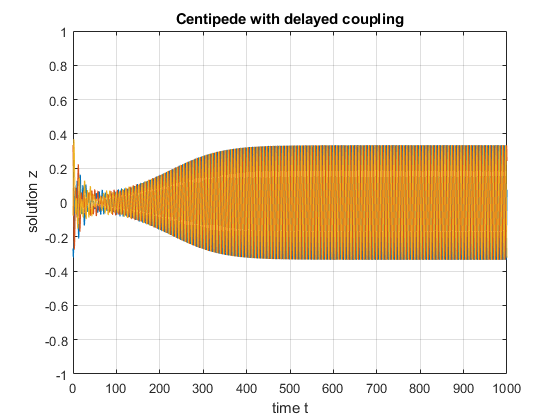

dde_z = kron(eye(n),Z)*sol.y;
dde_zs = dde_z + fliplr(offset)';
time = sol.x;

figure;
plot(time,dde_z)
title('Centipede with delayed coupling');
xlabel('time t');
ylabel('solution z');
ylim([-1 1])
grid on


[omega_s, T_s, amp_s, fi_s, DC_s] = osciprof(dde_z,time,n);

Frequency is equal to 0.85554
Period is equal to 7.3441
DC is 
  -0.002140208239402
   0.001912633525751
   0.000312013292077

Amplitudes are equal to 
   0.336271699329087
   0.332218883941088
   0.333819528719740

The phase shift is (RAD)
                   0
   2.085139478277866
  -2.096575818485510

The phase shift is (DEG)
   1.0e+02 *

                   0
   1.194696918014321
  -1.201249458284059




q_s = amp_s.*exp(1i*fi_s);
y_s = DC_s + q_s;
g_s = [fi_s;amp_s;DC_s;omega_s];


%return

### Describing function and MHB

%% Transfer function for LTI part

%% Intitial Conditions
g0 = randn(3*nn+1,1);  

%% Parameters for optimization
fre = abs(imag(eigenvalues.l1(1)));     % first guess of the oscillatory frequency
Beta = 2;                               % feasible region for amplitudes and offset
NumOfStP = 10;                          % number of different initial conditions

tic

rpts = RandomStartPointSet('NumStartPoints',NumOfStP);

[lbound,ubound] = boundsconst_fullsynch(g0,om_star,Beta);
ms = MultiStart('Display','iter','FunctionTolerance',1e-8,'XTolerance',1e-8);

opts = optimoptions(@fmincon,'Algorithm','interior-point','MaxFunctionEvaluations',120000);
problem = createOptimProblem('fmincon','x0',g0,...
    'objective',@CENcostfun,'lb',lbound,'ub',ubound,...
    'options',opts);


[xmin,fmin,flag,outpt,allmins] = run(ms,problem,rpts);


    Run       Local       Local      Local    Local   First-order
   Index     exitflag      f(x)     # iter   F-count   optimality
       1         1     3.03e-08       103      1161     2.567e-07
       2         1    3.047e-08        66       744     5.545e-07
       3         1     1.94e-07        94      1052     7.888e-07
       4         1    3.036e-08        73       821     3.445e-07
       5         1     3.12e-08        73       827      3.39e-07
       6         1    1.673e-09        82       930     2.242e-07
       7         1    3.034e-08        81       905     3.067e-07
       8         1    3.038e-08        68       762      2.56e-07
       9         1    3.037e-08        55       618     9.796e-07
      10         1    3.038e-08        98      1102      2.56e-07

MultiStart completed the runs from all start points.

All 10 local solver runs converged with a positive local solver exit flag.



toc

Elapsed time is 7.015657 seconds.


### Examine Stability 

 
GG = [allmins.X];
fval = [allmins.Fval];
[k,ii]=size(GG); i=1; ACC=[]; LAMDA=[];


### Reading solution


g = GG(:,8);

[g,q,omega,amp,fi,b] = ReadSolution_shifted(g,k);

Frequency is equal to 0.8557
Period is equal to 7.3427
DC is 
   1.0e-04 *

   0.859743013582508
   0.859421101711289
   0.863446344759220

Amplitudes are equal to 
   0.337232975461905
   0.337232961126784
   0.337233073719342

The phase shift is (RAD)
   5.209279301464203
   1.020489871959770
   3.114884859768484

The phase shift is (DEG)
   1.0e+02 *

   2.984697182787565
   0.584697626991406
   1.784697561339334




dDC = 100*norm(b-DC_s)/norm(DC_s)

dDC =      1.000456107572511e+02


dAmp = 100*norm(amp-amp_s)/norm(amp_s)

dAmp =    1.061264103708909


dOmega = 100*norm(omega-omega_s)/norm(omega_s)

dOmega =    0.018670514057831




 %% Oscillations

% [tiq,qsim] = Oscillations_shifted(amp,b,omega,ifi,fi,offset-offset,tend);
% 
% figure;
% plot(tiq,qsim)
% title('DMHB');
% xlabel('time t');
% ylabel('solution z');
% grid on
